%{
ES115 - Final Project Aerospace Altitude & Speed Profile Analyzer
Author: Matthew Chietro, Evan Scheuritzel
Version: 2.1
Date: 2026-04-25

Purpose:
   Analyze real aircraft flight data (altitude and speed vs time),
   identify flight phases, visualize the profile, and compute metrics.

Input:
   CSV file containing:
       Timestamp
       Altitude
       Speed

Output:
   - Separate plots
   - Flight phase detection
   - Performance metrics
Engineering Algorithms:
   - Threshold-based phase classification
   - Numerical differentiation using rate of change
   - Logical indexing for cruise/descent sections
   - Data filtering and cleanup
   - Statistical averaging and maximum value detection

MATLAB tools/functions:
   readtable, plot, scatter, histogram, diff, mean, max,
   logical indexing, figure, xlabel, ylabel, title,
   legend, grid on, hold on, clear, clc, close all
%}


clc;            % Clear command window so output is clean
clear;          % Remove all variables from memory
close all;      % Close any open figures

%% Load Data
% Read flight data from CSV file into a table
data = readtable('AC7664_3f5d2722.csv');   % Change file name if needed

%% Extract Variables
% Pull out each column from the table
time = data.Timestamp;    % Get time data
altitude = data.Altitude; % Get altitude data
speed = data.Speed;       % Get speed data

% Convert time to minutes from start
% Subtract first timestamp so it starts at 0, then convert seconds to minutes
time = (time - time(1)) / 60;

%% Clean Data
% Find only valid altitude values (ignore negative or bad data)
valid = altitude >= 0;

% Keep only valid rows
time = time(valid);
altitude = altitude(valid);
speed = speed(valid);


%% Phase Detection
% Create empty list of flight phases
phase = strings(size(time));

% Loop through each time step starting from second value
for i = 2:length(time)

    % Check if aircraft is low and slow -> Takeoff
    if altitude(i) < 3000 && speed(i) < 200 && i < length(time)/2
        phase(i) = "Takeoff";

          % If at high altitude -> Cruise
    elseif altitude(i) >= max(altitude)-200 || altitude(i)-altitude(i-1) <= 25 && speed(i) < 100 && i < length(time)/4
        phase(i) = "Cruise";

    % Check if altitude is increasing but still climbing range
    elseif altitude(i) > altitude(i-1)-100 && altitude(i) <  max(altitude) && phase(i) ~= "Cruise" && i < length(time)/2
        phase(i) = "Climb";
  
    % If altitude is decreasing -> Descent
    elseif altitude(i) < altitude(i-1) && phase(i) ~= "Climb"
        phase(i) = "Descent";

    % Anything else not classified
    else
        phase(i) = "Descent";
    end

end


%% Metrics
% Compute climb rate as change in altitude over change in time
climbRate = diff(altitude) ./ diff(time);

% Find fastest climb rate
maxClimbRate = max(climbRate);

% Find cruise data points
cruiseIndex = phase == "Cruise";

% Average speed during cruise phase
avgCruiseSpeed = mean(speed(cruiseIndex));

% Find descent points
descentIndex = phase == "Descent";

% Estimate total descent time
descentDuration = sum(descentIndex) * mean(diff(time));


%% Display Results
% Print computed values to command window
fprintf('Maximum Climb Rate: %.2f ft/min\n', maxClimbRate);

Maximum Climb Rate: 42750.00 ft/min


fprintf('Average Cruise Speed: %.2f knots\n', avgCruiseSpeed);

Average Cruise Speed: 336.58 knots


fprintf('Descent Duration: %.2f minutes\n', descentDuration);

Descent Duration: 33.99 minutes


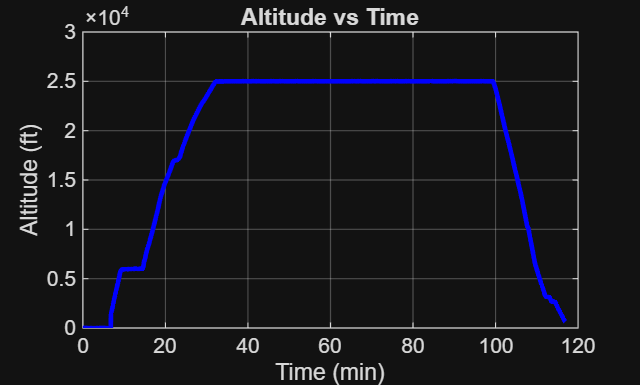


%% Plot 1: Altitude vs Time
figure; % Create new figure window
plot(time, altitude, 'b', 'LineWidth', 2) % Plot altitude in blue
grid on % Turn grid on for readability
xlabel('Time (min)') % Label x-axis
ylabel('Altitude (ft)') % Label y-axis
title('Altitude vs Time') % Add title

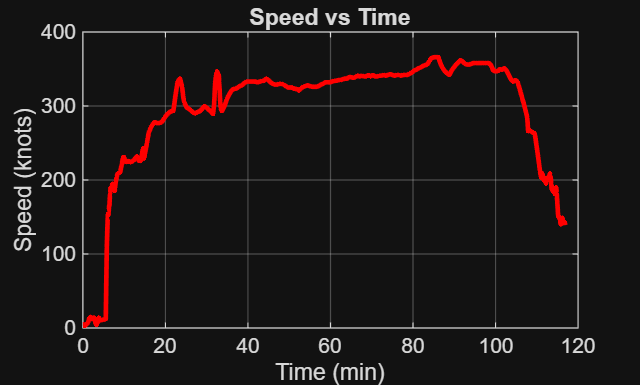


%% Plot 2: Speed vs Time
figure; % New figure
plot(time, speed, 'r', 'LineWidth', 2) % Plot speed in red
grid on
xlabel('Time (min)')
ylabel('Speed (knots)')
title('Speed vs Time')

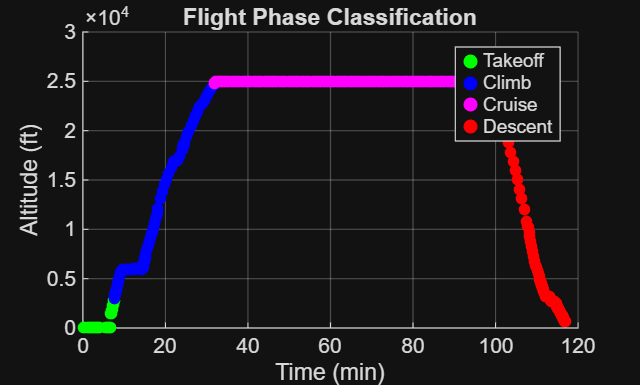


%% Plot 3: Flight Phases
figure; % New figure
hold on % Allow multiple plots on same graph
grid on

% Plot each phase with different color
scatter(time(phase=="Takeoff"), altitude(phase=="Takeoff"), 25, 'g', 'filled')
scatter(time(phase=="Climb"), altitude(phase=="Climb"), 25, 'b', 'filled')
scatter(time(phase=="Cruise"), altitude(phase=="Cruise"), 25, 'magenta', 'filled')
scatter(time(phase=="Descent"), altitude(phase=="Descent"), 25, 'r', 'filled')
scatter(time(phase=="Other"), altitude(phase=="Other"), 25, 'cyan', 'filled')

xlabel('Time (min)')
ylabel('Altitude (ft)')
title('Flight Phase Classification')
legend('Takeoff','Climb','Cruise','Descent')

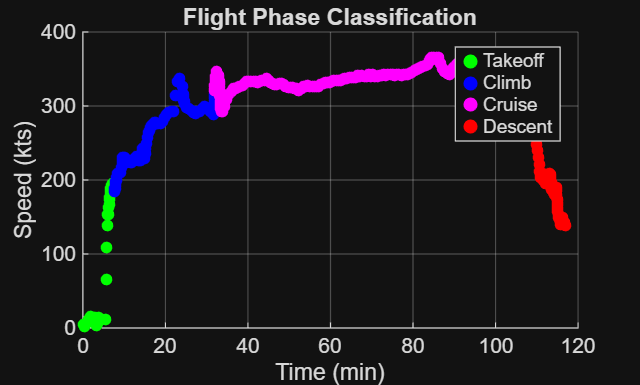


%% plot3.5: Speed Phases
figure; % New figure
hold on % Allow multiple plots on same graph
grid on

% Plot each phase with different color
scatter(time(phase=="Takeoff"), speed(phase=="Takeoff"), 25, 'g', 'filled')
scatter(time(phase=="Climb"), speed(phase=="Climb"), 25, 'b', 'filled')
scatter(time(phase=="Cruise"), speed(phase=="Cruise"), 25, 'magenta', 'filled')
scatter(time(phase=="Descent"), speed(phase=="Descent"), 25, 'r', 'filled')
scatter(time(phase=="Other"), speed(phase=="Other"), 25, 'cyan', 'filled')

xlabel('Time (min)')
ylabel('Speed (kts)')
title('Flight Phase Classification')
legend('Takeoff','Climb','Cruise','Descent')

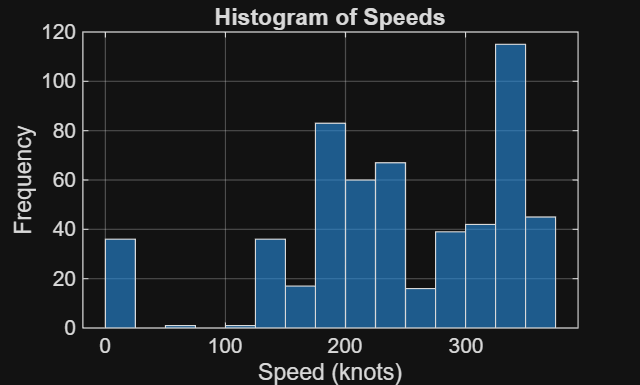


%% Plot 4: Speed Histogram
figure; % New figure
histogram(speed,15) % Split speed into 15 bins
grid on
xlabel('Speed (knots)')
ylabel('Frequency')
title('Histogram of Speeds')